# `Performance Testing / Characterization Script`

Read in JSON File for simulation configuration

clear;

david_file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
kristen_file_path = "/home/kristenangell/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
json_text = fileread(kristen_file_path + "test_config.json");
sim_config = jsondecode(json_text);
json_text_plot = fileread(kristen_file_path + "plot_config.json");
plot_config = jsondecode(json_text_plot);

Setup parameters from JSON file 

NUM_RUNS = sim_config.TestSettings.Configurations.num_runs;
FRAMES_PER_RUN = sim_config.TestSettings.Configurations.frames_per_sim;
PRE_ATTACK_FRAMES = sim_config.TestSettings.Configurations.pre_attack_frames;
MAX_BIN = sim_config.TestSettings.Configurations.max_bin;
BIN_WIDTH = sim_config.TestSettings.Configurations.bin_width;

TOTAL_FRAMES = NUM_RUNS * (FRAMES_PER_RUN-PRE_ATTACK_FRAMES);

Progress bar initialization

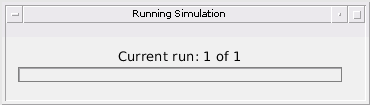

status = sprintf("Current run: %d of %d",1, NUM_RUNS);
progress_bar = waitbar(0,status,"Name","Running Simulation");

Declare the simulation

sim = Simulation_reconfigurable();
values = zeros(0,0);
raw_data = zeros(0,0);

Run simulation for NUM_RUNS, each time with different configuration

for run_idx = 1: NUM_RUNS
    status = sprintf("Current run: %d or %d",run_idx, NUM_RUNS);
%    waitbar(run_idx/NUM_RUNS,progress_bar,status);

    target_velocity = sign(randn) * randi(35)
    target_start = randi(138)+ 5;
    sim.initialize_simulation(sim_config, target_start, target_velocity);
    
    sim.run_simulation();

    [detected, actual_ranges, estimated_ranges, estimated_velocities, actual_velocities, error_ranges, error_velocities, false_positives] = sim.simulation_results();

    raw_data = [raw_data; detected', false_positives, actual_ranges', estimated_ranges, error_ranges, actual_velocities', estimated_velocities, error_velocities];

    values = [values; actual_ranges(PRE_ATTACK_FRAMES+1:end)', actual_velocities(PRE_ATTACK_FRAMES+1:end)', detected(PRE_ATTACK_FRAMES+1:end)', estimated_ranges(PRE_ATTACK_FRAMES+1:end,1), error_ranges(PRE_ATTACK_FRAMES+1:end,1), estimated_velocities(PRE_ATTACK_FRAMES+1:end,1), error_velocities(PRE_ATTACK_FRAMES+1:end,1), false_positives(PRE_ATTACK_FRAMES+1:end,1)];
end

target_velocity = -7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges =    57.7734       NaN       NaN       NaN       NaN
   57.9741       NaN       NaN       NaN       NaN
   58.5767       NaN       NaN       NaN       NaN
   59.0813       NaN       NaN       NaN       NaN
   59.5055       NaN       NaN       NaN       NaN
   82.5134   82.5333   82.5327   82.5470   82.5397
   62.5166   62.5032   62.5212   62.5185   62.5245
   62.7439   62.7122   62.7477   62.7427   62.7538
   62.8863   62.8875   62.8526   62.9044   62.8591
   58.5844   58.5741   58.5727   58.5548       NaN


actual_ranges =    63.0000   62.6999   62.3997   62.0996   61.7995   61.4993   61.1992   60.8990   60.5989   60.2988


estimated_velocities =     9.0199       NaN       NaN       NaN       NaN
    9.0164       NaN       NaN       NaN       NaN
    9.0324       NaN       NaN       NaN       NaN
    9.0176       NaN       NaN       NaN       NaN
    9.0229       NaN       NaN       NaN       NaN
   31.5986   17.9764    6.0279   -5.9597  -16.1858
  -23.2856   22.4785    5.9963  -10.3997  -28.9057
  -12.8034   24.8783   17.7483    6.0056   -5.7471
   24.2584    6.0827  -12.4123  -22.0868  -33.5536
  -31.6318    6.0272   -1.3746  -23.7545       NaN


actual_velocities =      9     9     9     9     9     9     9     9     9     9


detected =      0     0     0     0     0     0     0     0     0     0


col_detection =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Organize data into table

table_graph_data = array2table(values,"VariableNames",["Range (m)","Velocity (m/s)","Detected","Estimated Range (m)", "Error Range (m)", "Estimated Velocity (m/s)", "Error Velocity (m)", "False Positives"]);
writematrix(raw_data, 'raw_data.csv');
writetable(table_graph_data,'run_table_data.csv','WriteRowNames',true); 
%track attack spoofing accuracy

### **Plot P(detection) and P(false positive) vs. Range Histogram as a sanity check for individual runs **

range_col = values(:,1);
bin_classification = cast(range_col/BIN_WIDTH, "int16")';
histogram_vals = zeros(MAX_BIN,3);
bin_counts = zeros(MAX_BIN, 3);

for bin_num = 1:MAX_BIN
    histogram_vals(bin_num, 1) = bin_num;
    count = 0;
    detected = 0;
    false_pos = 0;
    for frame = 1: TOTAL_FRAMES
        if (bin_classification(frame) == bin_num)
            count = count + 1;
            if table_graph_data{frame, 3}
                detected = detected + 1;
            end
            if table_graph_data{frame, 8}
                false_pos = false_pos + 1;
            end
        end
    end
        bin_counts(bin_num, 2) = detected;
        bin_counts(bin_num, 3) = false_pos;
    if (count ~= 0)
        histogram_vals(bin_num, 2) = detected/count;
        histogram_vals(bin_num, 3) = false_pos/count;
    end
end
bin_counts_table = array2table(bin_counts, "VariableNames", ["Bin #", "Detected Count", "False Pos. Count"])

bin_counts_table = 30×3 table
    Bin #    Detected Count    False Pos. Count
    _____    ______________    ________________

      0            0                  0        
      0            0                  0        
      0            0                  0        
      0            0                  0        
      0            0                  0        
      0            0                  0        
      0            0                  0        
      0            0                  0        
      0            0                  0        
      0            0                  0        
      0            0                  0        
      0            0                  5        
      0            0                  0        
      0            0                  0        
      0            0                  0        
      0            0                  0        


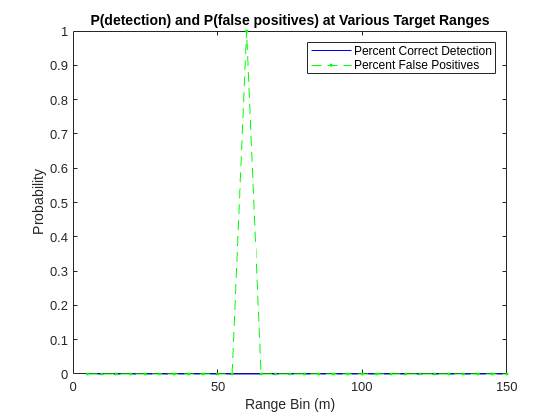

figure
plot(histogram_vals(:,1)*BIN_WIDTH, histogram_vals(:,2), 'b');
hold on
plot(histogram_vals(:,1)*BIN_WIDTH, histogram_vals(:,3), '--.g');
hold off
ylabel("Probability")
xlabel("Range Bin (m)")
legend("Percent Correct Detection", "Percent False Positives")
title("P(detection) and P(false positives) at Various Target Ranges")
saveas(gcf, "histogram_plot.png")

### **Plot Error vs. Range**

%% Error vs Range
range_error_plot = zeros(0,0);
for frame = 1: TOTAL_FRAMES
    val = table_graph_data{frame, 3};
    if (val(1) ~= 0)
        range_error_plot = [range_error_plot; [table_graph_data{frame, 1}, table_graph_data{frame, 5}]];
    end
end

figure
scatter(range_error_plot(:,1), range_error_plot(:,2));

Index in position 2 exceeds array bounds.

ylabel("Range Error (m)")
xlabel("Range (m)")
title("Range Error at Various Distances")
saveas(gcf, "error_plot.png")
